# **Modern Control Project (Fall 2023)**

### **Sepehr Jahangiri 9923016**

### **Mohadese Rezaei 9923034**

### **Sina Fazel 9923058**

### **Dorsa Rahmati 9923110**

### parameters

clc;clear;close;
% Parameters:
Ixx=2.3*10^-3; %inertia
Iyy=2.3*10^-3;
Izz=5.09*10^-3;
m=1; %mass
g=9.806; %gravitational acceleration

### State Space

syms X Y Z X_dot Y_dot Z_dot theta theta_dot psi psi_dot phi phi_dot p q r
syms Omega_1 Omega_2 Omega_3 Omega_4 u_1 u_2 u_3 u_4
u=[u_1,u_2,u_3,u_4] %inputs

$$u = \left(\begin{array}{cccc} u_{1} & u_{2} & u_{3} & u_{4} \end{array}\right)$$

x=[X,X_dot,Y,Y_dot,Z,Z_dot,phi,theta,psi,p,q,r] %states

$$x = \left(\begin{array}{cccccccccccc} X & \dot{X} & Y & \dot{Y} & Z & \dot{Z} & \varphi & \theta & \psi & p & q & r \end{array}\right)$$

F=[X_dot;(cos(phi)*sin(theta)*cos(psi)+sin(phi)*sin(psi))*u_1/m;
    Y_dot;(cos(phi)*sin(theta)*sin(psi)-sin(phi)*cos(psi))*u_1/m;
    Z_dot;(cos(theta)*cos(phi)*u_1/m-g);
 p+q*sin(phi)*tan(theta)+r*cos(phi)*tan(theta);
 q*cos(phi)-r*sin(phi);
 q*sin(phi)*sec(theta)+r*cos(phi)*sec(theta);
 (q*r*(Iyy-Izz))/(Ixx)+u_2/Ixx;
 (p*r*(Izz-Ixx))/(Iyy)+u_3/Iyy;
 (q*p*(Ixx-Iyy))/(Izz)+u_4/Izz] %x_dot=F(x,u)

$$F = \left(\begin{array}{c} \dot{X}\\ u_{1}\,\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)\\ \dot{Y}\\ -u_{1}\,\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)\\ \dot{Z}\\ u_{1}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-\frac{4903}{500}\\ p+r\,\cos\left(\varphi \right)\,\tan\left(\theta \right)+q\,\sin\left(\varphi \right)\,\tan\left(\theta \right)\\ q\,\cos\left(\varphi \right)-r\,\sin\left(\varphi \right)\\ \frac{r\,\cos\left(\varphi \right)}{\cos\left(\theta \right)}+\frac{q\,\sin\left(\varphi \right)}{\cos\left(\theta \right)}\\ \frac{10000\,u_{2}}{23}-\frac{279\,q\,r}{230}\\ \frac{10000\,u_{3}}{23}+\frac{279\,p\,r}{230}\\ \frac{100000\,u_{4}}{509} \end{array}\right)$$

C=[1 0 0 0 0 0 0 0 0 0 0 0;
    0 0 1 0 0 0 0 0 0 0 0 0;
    0 0 0 0 1 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0 1 0 0 0]

C =      1     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0


Cs=C;
D=[0 0 0 0;0 0 0 0;0 0 0 0;0 0 0 0]

D =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


### Linearization

As=jacobian(F,x);
Bs=jacobian(F,u);
Ep=[0,0,0,0,0,0,0,0,0,0,0,0,g*m,0,0,0]; %equilibrium point
x_EP=zeros(12,1);
y_EP=zeros(4,1);
u_EP=[g*m;0;0;0];
A=subs(As,[x,u],Ep)

$$A = \left(\begin{array}{cccccccccccc} 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{4903}{500} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & -\frac{4903}{500} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

B=subs(Bs,[x,u],Ep)

$$B = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & \frac{10000}{23} & 0 & 0\\ 0 & 0 & \frac{10000}{23} & 0\\ 0 & 0 & 0 & \frac{100000}{509} \end{array}\right)$$

A=double(A);
B=double(B);
sys=ss(A,B,C,D);

### Jordan form

[T,~]=jordan(A)

T =     9.8060         0         0         0         0         0         0         0         0         0         0         0
         0    9.8060         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0   -9.8060         0         0         0         0         0
         0         0         0         0         0         0         0   -9.8060         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    1.0000         0         0         0
         0         0    1.0000         0         0         0         0         0         0         0         0         0
         0         0        

A_J=T\A*T

A_J =      0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0


B_J=T\B;
C_J=C*T;
D_J=D;
sysJ=ss2ss(sys,T);
x_J=(T\(x.')).'

$$x\_J = \left(\begin{array}{cccccccccccc} \frac{500\,X}{4903} & \frac{500\,\dot{X}}{4903} & \theta & q & Z & \dot{Z} & -\frac{500\,Y}{4903} & -\frac{500\,\dot{Y}}{4903} & \varphi & p & \psi & r \end{array}\right)$$

### Eigen Values and minimal polynomial

[V,~]=eig(A); %eigen vector
eig(A) %eigen value

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


syms lambda
mp = minpoly(A,lambda) %minimal polynomial

$$mp = \lambda^{4}$$

### Transfer Function

syms s
Qs = inv(s*eye(12)-A); 
G=C*Qs*B %#ok

$$G = \left(\begin{array}{cccc} 0 & 0 & \frac{98060}{23\,s^{4}} & 0\\ 0 & -\frac{98060}{23\,s^{4}} & 0 & 0\\ \frac{1}{s^{2}} & 0 & 0 & 0\\ 0 & 0 & 0 & \frac{100000}{509\,s^{2}} \end{array}\right)$$

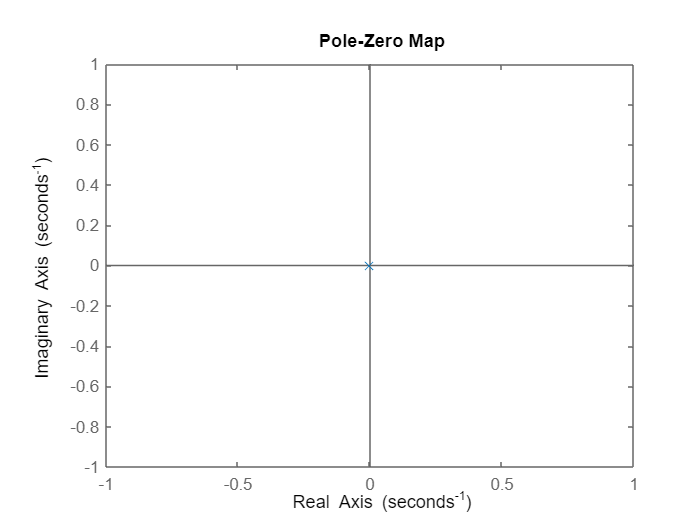

Tf=tf(sys);
figure
pzmap(sys) % all poles on zero

### State transfer matrix

Qt=ilaplace(Qs); %transfer matrix
vpa(Qt,6)

$$ans = \begin{array}{l} \left(\begin{array}{cccccccccccc} 1.0 & t & 0 & 0 & 0 & 0 & 0 & 4.903\,t^{2} & 0 & 0 & 1.63433\,t^{3} & 0\\ 0 & 1.0 & 0 & 0 & 0 & 0 & 0 & 9.806\,t & 0 & 0 & 4.903\,t^{2} & 0\\ 0 & 0 & 1.0 & t & 0 & 0 & \sigma_{1} & 0 & 0 & -1.63433\,t^{3} & 0 & 0\\ 0 & 0 & 0 & 1.0 & 0 & 0 & -9.806\,t & 0 & 0 & \sigma_{1} & 0 & 0\\ 0 & 0 & 0 & 0 & 1.0 & t & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1.0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1.0 & 0 & 0 & t & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1.0 & 0 & 0 & t & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1.0 & 0 & 0 & t\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1.0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1.0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-4.903\,t^{2} \end{array}$$

### Step Respond and Initial condition respond

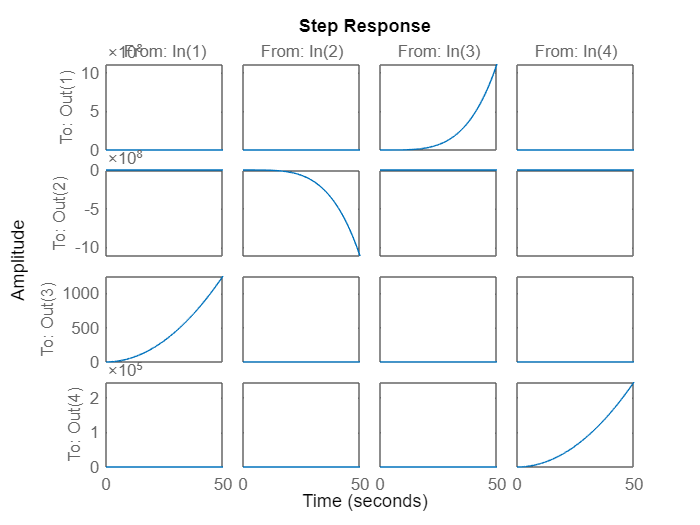

X0=[1 0 0.5 0 0 1 1 0 0 1 1 0].'; %initial condition
figure;step(sys)

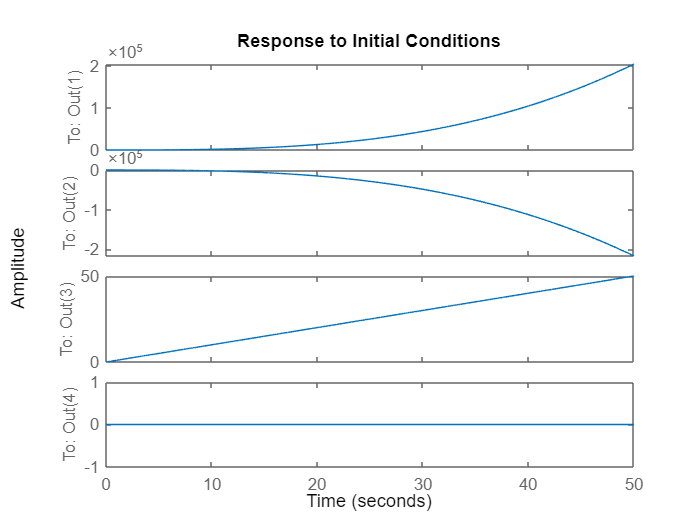

figure;initial(sys,X0)

%U=[1/s;0.1/s;0.1/s;0.05/s]; %input
%Xs=Qs*X0+Qs*B*U; %#ok
%Ys=C*Qs*X0+C*Qs*B*U+D*U; %#ok 
%Xt=ilaplace(Xs);
%xt=vpa(simplify(Xt),6);
%Yt=ilaplace(Ys);
%yt=vpa(simplify(Yt),6) %output
%t=0:0.001:0.2;
%y=[polyval(sym2poly(yt(1)),t);
%polyval(sym2poly(yt(2)),t);
%polyval(sym2poly(yt(3)),t);
%polyval(sym2poly(yt(4)),t);
%polyval(sym2poly(yt(5)),t);
%polyval(sym2poly(yt(6)),t)];
%figure()
%plot(t,y(1,:),t,y(2,:),t,y(3,:),t,y(4,:),t,y(5,:),t,y(6,:));legend("X","Y","Z","phi","theta","psi");grid on;

### Controllability And Observability

Co=ctrb(A,B);
Ob=obsv(A,C);
Cout=[C*Co,D];
rank(Co)

ans = 12

rank(Ob)

ans = 12

rank(Cout)

ans = 4

### Controller

#### Static Pre-Compensation

Pole Placement

poles_s=[-.4+.4j,-.4-.4j,-2.0,-2.0,-2.0,-2.0,-2.4,-2.4,-2.4,-2.4,-2.8,-2.8];
ks_pp=place(A,B,poles_s)

ks_pp =     0.0000    0.0000    0.0000    0.0000    4.8000    4.4000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0009   -0.0012   -0.0000   -0.0032   -0.0000   -0.0000    0.0396   -0.0049   -0.0000    0.0166   -0.0007   -0.0000
    0.0025    0.0063   -0.0033   -0.0042    0.0000    0.0000    0.0173    0.0524    0.0000    0.0024    0.0184    0.0000
    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0244    0.0000    0.0000    0.0224


LQR

Qs=diag([1,1,1,1,10,4,20,20,1,0,0,0]);
Rs=diag([1,1,1,1]);
[ks_lqr,~,~]=lqr(sys,Qs,Rs)

ks_lqr =    -0.0000   -0.0000    0.0000    0.0000    3.1623    3.2132   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -1.0000   -1.4148   -0.0000   -0.0000    4.9118   -0.0000    0.0000    0.1503   -0.0000    0.0000
    1.0000    1.4148   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    4.9118    0.0000    0.0000    0.1503    0.0000
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.1009


#### Dynamic Pre-Compensation

pole placement

poles_d=[-.5+.5j,-.5-.5j,-4,-4,-6,-6,-6,-6,-8,-8,-8,-8,-9,-9,-9,-9];
Ai=[[A;-C],zeros(16,4)];
Bi=[B;zeros(4,4)];
rank(ctrb(Ai,Bi))

ans = 16

k_pp=place(Ai,Bi,poles_d);
kd_pp=k_pp(:,1:12)

kd_pp =     0.0000    0.0000   -0.0000   -0.0000  174.0000   23.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.5575    0.1315   -0.4681   -0.2794   -0.0000   -0.0000    0.6265    0.1309   -0.0000    0.0626    0.0048   -0.0000
    0.6071    0.3121    0.0400    0.0094    0.0000    0.0000   -0.0094    0.6592    0.0000   -0.0003    0.0639    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.8857    0.0000   -0.0000    0.1171


ka_pp=k_pp(:,13:16)

ka_pp =    -0.0000   -0.0000 -432.0000    0.0000
   -0.8540    0.0962    0.0000    0.0000
   -0.3091   -0.0613   -0.0000   -0.0000
    0.0000    0.0000    0.0000   -2.1989


LQR

Qd=diag([0,0,0,0,0,0,100,100,0,0,0,0,1000,1000,1000,1000]);
Rd=diag([0.1,0.1,0.1,0.1]);
[k_lqr,~,~]=lqr(Ai,Bi,Qd,Rd);
kd_lqr=k_lqr(:,1:12)

kd_lqr =     0.0000    0.0000   -0.0000   -0.0000   43.0887    9.2832    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.0000    0.0000  -64.8660  -21.0380   -0.0000   -0.0000   34.0647    0.0000   -0.0000    0.3959    0.0000   -0.0000
   64.8660   21.0380   -0.0000   -0.0000   -0.0000    0.0000    0.0000   34.0647    0.0000    0.0000    0.3959    0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    7.4120   -0.0000    0.0000    0.2747


eig(Ai-Bi*k_lqr)

ans =  -82.9127 +82.9127i
 -82.9127 -82.9127i
 -82.9127 +82.9127i
 -82.9127 -82.9127i
 -13.4916 +23.3682i
 -13.4916 -23.3682i
 -26.9832 + 0.0000i
  -1.5708 + 2.7208i
  -1.5708 - 2.7208i
  -1.5708 + 2.7208i


ka_lqr=k_lqr(:,13:16)

ka_lqr =    -0.0000    0.0000 -100.0000    0.0000
   -0.0000  100.0000    0.0000    0.0000
 -100.0000    0.0000    0.0000   -0.0000
   -0.0000   -0.0000    0.0000 -100.0000
